## Parte 0 

Natália Vieira Lima - RA 185483

### Dados de Entrada

Conforme descrito na função de *dígitosRA(RA)*  e *dados_problema(d)*, os dados utilizados para $L, \space I_{zz}
$ e $M_0$ foram convertidos a partir dos dados inseridos do RA. Os demais dados utilizados foram descritos no enunciados ou ajustados conforme a necessidade da análise.

RA = '185483';
d = digitosRA(RA);
[L,Izz,M0] = dados_problema(d);

## Parte 1

### Tensões e Deflexões em Vigas

P = M0/L;  % Forca aplicada (N)
E = 210e9; % Modulo de elasticidade do aco (Pa)

#### Momento Fletor

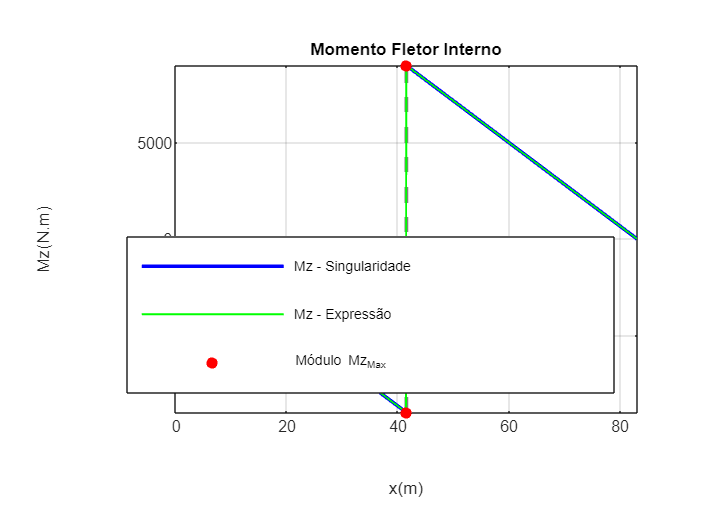

Mz = @(x) P*L - M0 -P*x + M0*sing(x,L/2,0);

x = [0:0.05:L];

Mz2 = momentoFletor(P,L,M0,x);
figure
fplot(Mz, [0 L], 'b', 'LineWidth',2);
hold on;

plot(x, Mz2, 'g','LineWidth',1);
title('Momento Fletor Interno');
plot(41.5, 9000, 'or', 'LineWidth', 0.05, 'MarkerFaceColor','r');
plot(41.5, -9000, 'or', 'LineWidth', 0.05, 'MarkerFaceColor','r');
grid on;
xlabel('x(m)'); 
ylabel('Mz(N.m)');
legend('Mz - Singularidade', 'Mz - Expressão', 'Módulo Mz_{Max}','Location','southeast');
hold off;

Podemos verificar no gráfico que o módulo do momento fletor é máximo para $x = \frac{L}{2}
$.

#### Deflexão

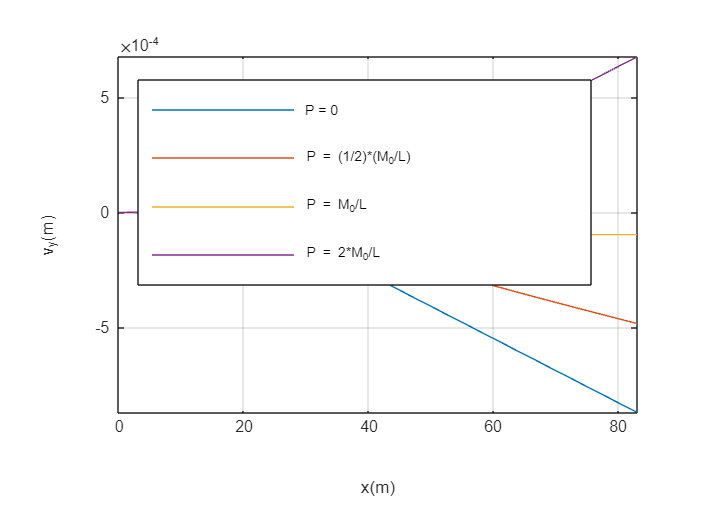

% Calculo da deflexao por diferentes valores da forca P
P1 = 0;
v1 = @(x) ((P1*L-M0)*(x.^2/2)-(P1/6)*x.^3+(M0/2)*(sing(x, L/2,2)))/(E*Izz);

P2 = (1/2)*(M0/L);
v2 = @(x) ((P2*L-M0)*(x.^2/2)-(P2/6)*x.^3+(M0/2)*(sing(x, L/2,2)))/(E*Izz);

P3 = M0/L;
v3 = @(x) ((P3*L-M0)*(x.^2/2)-(P3/6)*x.^3+(M0/2)*(sing(x, L/2,2)))/(E*Izz);

P4 = 2*M0/L;
v4 = @(x) ((P4*L-M0)*(x.^2/2)-(P4/6)*x.^3+(M0/2)*(sing(x, L/2,2)))/(E*Izz);

% Grafico das 4 funcoes juntas
figure;
fplot(v1, [0 L]);
hold on;
fplot(v2, [0 L]);
fplot(v3, [0 L]);
fplot(v4, [0 L]);
grid on;
xlabel('x(m)'); 
ylabel('v_y(m)'); 
legend('P = 0', 'P = (1/2)*(M_0/L)', 'P = M_0/L', 'P = 2*M_0/L', 'Location','northwest');

hold off;

Conforme visualizado no gráfico resultante das deflexões pela posição a partir de diferentes intensidades da força aplicada. Desse modo, visualizamos que conforme maior seja a intensidade da força aplicada, maior será a deflexão da viga.

#### Tensão

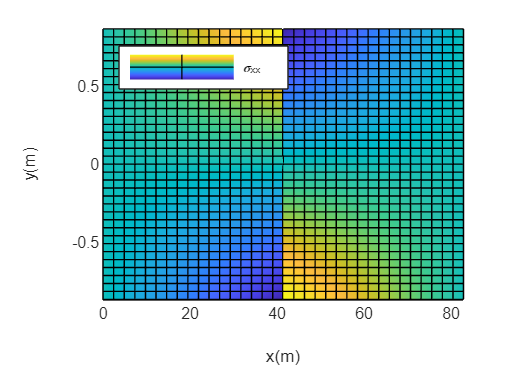

% Calculo das variaveis
d3 = d(3); d4 = d(4);
b = (10*d3 + 2*d4)*0.01;         % b convertido em m
h = 3*b;

% Calculo da tensao
Sxx = @(x,y) -Mz(x).*y/Izz;

% Grafico de superficie
figure
fsurf(Sxx,[0 L -h/2 h/2]);
xlabel('x(m)'); 
ylabel('y(m)');
legend('\sigma_{xx}', 'Location','northwest');

view(2); % visualizacao por cima

Para a construção dos gráficos acima foi utilizada a função [fplot](https://www.mathworks.com/help/matlab/ref/fplot.html), onde na declaração da função você informa qual é a variável dessa e, para a construção do gráfico, ela mesma inscrementa na discretização das variáveis. Ademais, cabe ressaltar que ao utilizar diferentes unidades para as variáveis, o impacto seria na variação da ordem dos eixos das abscissas e ordenadas e não no comportamento da curva ou superfície em si.

## Parte 2

### Deflexão em função da carga P

% Calculo da deflexao variando a forca P
v = @(P5) ((P5*L-M0)*(L.^2/2)-(P5/6)*L.^3+(M0/2)*(sing(L, L/2,2)))/(E*Izz);

% v = 0 entre P = 236 e 246
P0 = fzero(v, 246)

P0 = 243.9759

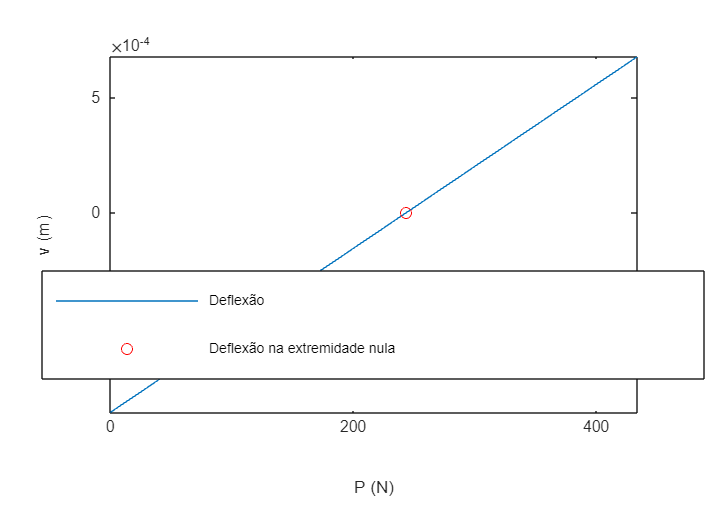


% Grafico
figure;
fplot(v, [0 2*M0/L]);
hold on;
plot(P0,v(P0), 'or'); % raiz da deflexao
hold off;

xlabel('P (N)'); 
ylabel('v (m)'); 
legend('Deflexão', 'Deflexão na extremidade nula', 'Location','best');

O algoritmo de busca de raízes utilizado foi dado pela função [fzero = (fun, x0)](https://www.mathworks.com/help/matlab/ref/fzero.html), esse algoritmo utiliza como base uma combinação do método da Secante, Bissecante e Interpolação por Quadrados Mínimos, conforme descrito na documentação da função.

Para sua utilização, considerei que o resultado da raiz estimado (x0) estaria próximo de 246, pois ao plotar a deflexão (v) pela força (P) mostrava que cruzava o eixo das abscissas no intervalo de$ P = [236, 246]$. Por fim, verificamos que o resultado obtido,  $P = 243,9759 \spaceN$, coincide com o visualizado graficamente.

## Parte 3

### Deflexão Máxima

v = @(x) ((P0*L-M0)*(x.^2/2)-(P0/6)*x.^3+(M0/2)*(sing(x, L/2,2)))/(E*Izz);

Temos de pontos nulos, mínimos e máximos da deflexão:

% Raiz da funcao 1
x_nulo1 = fzero(v, 0);
v_nulo1 = v(x_nulo1);
% Raiz da funcao 2
x_nulo2 = fzero(v, 30);
v_nulo2 = v(x_nulo2);
% Raiz da funcao 3
x_nulo3 = fzero(v, 80);
v_nulo3 = v(x_nulo3);

x_raizes = [x_nulo1, x_nulo2, x_nulo3] % quais valores de X provocam um v = 0

x_raizes =          0   27.6667   83.0000


v_raizes = [v_nulo1, v_nulo2, v_nulo3] % valores de V = 0 ou suficientemente proximo de 0

v_raizes = 1.0e-19 *

         0   -0.0218    0.3484


A deflexão nula foi encontrada em 3 pontos, utilizando novamente a função fzero. Considerou-se aqui uma aproximação para x0 de $(0 , \space30, \space 80)$m conforme uma aproximação válida ao visualizarmos o gráfico da deflexão (v) pela posição (x). Os valores resultantes são bem próximos do resultado esperado $(v = 0\spaceN)$, como podemos verificar também graficamente.

#### Pontos Mínimos e Máximo

x_min = fminbnd(v, 0, L)

x_min = 55.3333

v_min = v(x_min)

v_min = -3.2209e-05

x_max = fminbnd(@(x) -v(x), 0, L)

x_max = 18.4444

v_max = v(x_max)

v_max = 2.3859e-06

Para esses pontos, a função utilizada foi a [fminbnd](https://www.mathworks.com/help/matlab/ref/fminbnd.html#bvadyg6-12), essa função interpola os dados da parábola de modo que calcula o mínimo e máximo. Novamente, os valores resultantes também coincidem com os visualizados graficamente.

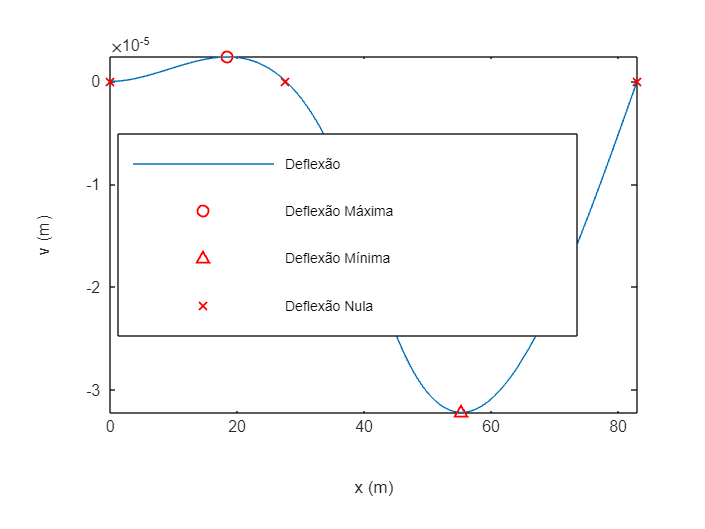

% Grafico da funcao com os pontos maximos, minimos e nulos
figure;
fplot(v, [0 L]);
hold on;
plot(x_max, v_max,'or', 'LineWidth', 1);
plot(x_min, v_min, '^r', 'LineWidth', 1);
% Zeros da funcao:
plot(x_nulo1, v_nulo1, 'xr', 'LineWidth', 1);
plot(x_nulo2, v_nulo2, 'xr', 'LineWidth', 1);
plot(x_nulo3, v_nulo3, 'xr', 'LineWidth', 1);
xlabel('x (m)'); 
ylabel('v (m)'); 
legend('Deflexão', 'Deflexão Máxima',  'Deflexão Mínima','Deflexão Nula','Location','best');
hold off;

## Parte 4

### Forças de Reação

Para a solução o Sistema Linear de Equações, foram utilizadas a resolução por matrizes $[A] \{x\} = [b]$, de modo que a matriz $[A]
$ corresponde a matriz dos coeficientes das variáveis $\{x\}=[R_a \space M_A \space R_D]^t$. Desse modo, foram calculados 4 casos de Sistema Linear conforme as considerações solicitadas (cada caso e a consideração realizada consta abaixo):

% Variaveis
p = 7850;
g = 9.81;
w0 = p*b*h*g;
P = M0/L;

% Coeficientes das variaveis [Ra Ma Rd]'
A = [L        1   0
    (3*L/2)   1   0
    1         0   1];

#### (1) Para $P = \frac{M0}{L}$:

b1 = [((L^2/2)*w0-M0)  ((3*L/2)^2/2*w0 - M0 -P*(3*L/2-L))  (3*L/2*w0 -P) ].';
Caso1 = A\b1     % resposta do sistema linear (1)

Caso1 = 1.0e+08 *

    0.0806
   -4.0154
    0.0161


#### (2) Para $w_0 = 0$:

w0 = 0;          % mudanca da variavel
b2 = [((L^2/2)*w0-M0)  ((3*L/2)^2/2*w0 - M0 -P*(3*L/2-L))  (3*L/2*w0 -P) ].';
Caso2 = A\b2     % resposta do sistema linear (2)

Caso2 =  -216.8675
         0
   -0.0000


#### (3) Para $w_0 = 0$ e $P = 0
$:

P = 0;          % mudanca da variavel
b3 = [((L^2/2)*w0-M0)  ((3*L/2)^2/2*w0 - M0 -P*(3*L/2-L))  (3*L/2*w0 -P) ].';
Caso3 = A\b3    % resposta do sistema linear (3)

Caso3 = 1.0e+04 *

   -0.0000
   -1.8000
         0


#### (4) Para $w_0 = 0, \space M_0 = 0, \spaceP = \frac{M_0}{L}$:

% mudanca das variaveis
P = M0/L;
M0 = 0;

b4 = [0  ( -P*(3*L/2-L))  ( -P) ].';
Caso4 = A\b4    % resposta do sistema linear (4)

Caso4 = 1.0e+04 *

   -0.0217
    1.8000
   -0.0000


#### Apresentação dos resultados

Para visualizar o resultado para cada caso do Sistema Linear foi utilizado o modo de visualização no formato tabela visualizado na Tabela. Cabe ressaltar que os dados referentes a linhas 1, 2 e 3 são correspondentes ao resultado do $R_A, \space M_A, 
$ e $R_D$ respectivamente.

T = table(Caso1, Caso2, Caso3, Caso4)

T = 3×4 table
       Caso1          Caso2          Caso3          Caso4   
    ___________    ___________    ___________    ___________

     8.0629e+06        -216.87    -2.9221e-14        -216.87
    -4.0154e+08              0         -18000          18000
     1.6126e+06    -2.8422e-14              0    -2.8422e-14


## Funções Utilizadas

function y = sing(x,a,n)
 % singularity function y = <x-a>^n
 y=(x-a).^n.*(x>=a);
end

function [L,Izz,M0] = dados_problema(d)
d5 = d(5);
d6 = d(6);

if(d5 == 0) && (d6 == 0)
    L = 5;
end

L = 10*d5 + d6;

%% Secao transversal
d3 = d(3);
d4 = d(4);

b = (10*d3 + 2*d4)*0.01;         % b convertido em m
h = 3*b;

%% Carregamento

d1 = d(1);
d2 = d(2);

M0 = (10*d1 + d2)*1000;      % M0 em N.m


%% Segundo Momento da area
Izz = (b*h^3)/12;
end
function [d] = digitosRA(RA)
% Pega o RA de entrada (string) e converte num vetor (d) de inteiros com 
% cada digito do RA ser uma posicao do vetor

ra = str2num(RA);
format short
r1 = rem(ra, 100000);
d1 = ra/100000 - r1/100000;

r2 = rem(r1, 10000);
d2 = r1/10000 - r2/10000;

r3 = rem(r2,1000);
d3 = r2/1000 - r3/1000;

r4 = rem(r3,100);
d4 = r3/100 - r4/100;

r5 = rem(r4,10);
d5 = r4/10 - r5/10;

r6 = rem(r5, 1);
d6 = r5 - r6;

d = [d1 d2 d3 d4 d5 d6];
end